# EKF-Based Landmark SLAM

This example shows how to use [ekfSLAM](docid:nav_ref#mw_87e7fb8b-24dc-4e2e-b094-8d8ccd00a873) for a reliable implementation of landmark Simultaneous Localization and Mapping (SLAM) using the Extended Kalman Filter (EKF) algorithm and maximum likelihood algorithm for data association. In this example, you create a landmark map of the immediate surroundings of a vehicle and simultaneously track the path of the vehicle. Generate a trajectory by moving the vehicle using the noisy control commands, and form the map using the landmarks it encounters along the path. Correct the vehicle trajectory and landmark estimates by observing the landmarks again.

## Load Data Set

Load a modified version of the Victoria Park data set that contains the controller inputs, measurements, GPS latitude and longitude, and dead reckoning generated using the controller inputs and motion model. 

load("victoriaParkDataset.mat","controllerInput", ...
     "measurements","gpsLatLong","deadReckoning");

## Set Up Parameters

Specify the initial vehicle state and state covariance.

initialState = [gpsLatLong(1,2) gpsLatLong(1,1) deg2rad(37)]';
initialCovar = eps*eye(3);

Specify the process noise covariance in velocity and steering commands.

sigmaVelocity = 2;      % [m/s]
sigmaSteer= deg2rad(6); % [rad]
processNoise = [sigmaVelocity^2 0; 0 sigmaSteer^2];

Specify the measurement covariance in range and bearing.

sigmaRange = 1;            % [m]
sigmaBearing = deg2rad(3); % [rad]
measCovar = [sigmaRange^2 sigmaBearing^2];

Specify the maximum range at which to check landmarks for association.

maxSensorRange = 30; % [m]

Specify the time step size in which the vehicle moves.

timeStep = 0.025; % [sec]

Specify the thresholds for the data association function, `nav.algs.associateMaxLikelihood`. The landmark rejection threshold is the chi-square ($\chi^{2}$) distribution table value for a 95% correct association.

landmarkRejectionThres = 5.991;  % maximum distance for association
landmarkAugmentationThres = 200; % minimum distance for creation of new landmark
validationGate = [landmarkRejectionThres landmarkAugmentationThres];

Set a flag that determines whether to plot the map during the run.

plotOnTheRun = false;

Get the number of samples from the data set.

numSamples = size(controllerInput,1);

## Initialize Figure or Progress Bar

If the live plot option is enabled, create a new figure and set up handles for plotting various components. Otherwise, create a wait bar that updates with the proportion of the data set that has been executed. Set the wait bar so that clicking Cancel stops an in-progress computation. Closing the wait bar stops the execution.

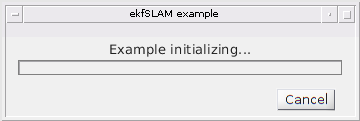

if plotOnTheRun
    [robotHandle,covarianceHandle,sensorHandle, ...
     observationHandle,landmarkHandle, ...
     deadRecHandle,estTrajHandle] = ...
        exampleHelperInitializeVisualizationEKFSLAM(initialState,gpsLatLong);
else
    waitBarHandle = waitbar(0,'Example initializing...', ...
        'Name','ekfSLAM example', ...
        'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
    setappdata(waitBarHandle,'canceling',0);
end

## Set Up ekfSLAM

Configure the [ekfSLAM](docid:nav_ref#mw_87e7fb8b-24dc-4e2e-b094-8d8ccd00a873) object using the initial state of the vehicle, initial state covariance, process noise covariance, and the motion model of the vehicle.

ekfSlamObj = ekfSLAM('State',initialState, ...
    'StateCovariance',initialCovar, ...
    'StateTransitionFcn',@exampleHelperVictoriaParkStateTransition);
ekfSlamObj.ProcessNoise = processNoise;
ekfSlamObj.MaxAssociationRange = maxSensorRange;

## Main Loop

The main loop consists of these primary operations:

- **Prediction** — Predict the next state based on the control command and the current state. 

- **Landmark Extraction **— Get the landmarks in the environment.

- **Correction **— Update the state and state covariance using the observed landmarks.

### Prediction

In this example, the vehicle moves relative to its previous state based on the control input while the landmarks remain stationary. Thus, only the state of the vehicle is propagated. Use the motion model of the vehicle to propagate the state of the vehicle to next time step using the data set. 

The [`predict`](docid:nav_ref#mw_3e12744b-13ef-4acb-8081-0e41295a9122) method calls the function specified in the `StateTransitionFcn` property of `ekfSlamObj` to predict the state of the vehicle. The `predict` method passes the control input, other necessary inputs, and the current vehicle pose to the `StateTransitionFcn.`

for count = 1:numSamples
    predict(ekfSlamObj,controllerInput(count,:),timeStep);

### Landmark Extraction

This example uses a list of observed landmarks from the data set, so you do not have to extract landmarks from the environment using a sensor. The landmarks are from a semi-circular region in front of the vehicle. The radius of the semi-circular region is defined by the maximum range of the sensor. 

    observedLandmarks = measurements{count};

### Correction

The `ekfSLAM` object corrects the state based on a given measurement, returning a list of matched landmarks and a list of new landmarks. The [`correct`](docid:nav_ref#mw_a8c3dd9e-951e-4d57-9ae5-c5b68565abb3) method uses the function specified in the `DataAssociationFcn` property of `ekfSlamObj` to associate the observed landmarks or measurements to known landmarks. The data association function returns a list of associations and a list of new landmarks. The `correct` method uses the associations to update the belief of the vehicle and the map using the correlation between the observed landmarks and the known landmarks. Additionally, the `correct` method augments the position and covariance of any new landmark in the `State` and `StateCovariance` vectors, respectively.

If the live plot option is enabled, update the figure with the scans at the current time.

  if ~isempty(observedLandmarks)
        correct(ekfSlamObj,observedLandmarks,measCovar,validationGate);
        % Update the corrected position of vehicle in the figure
        if plotOnTheRun
            exampleHelperUpdateScans(ekfSlamObj.State, ...
                              ekfSlamObj.MaxAssociationRange, ...
                              observedLandmarks, ...
                              sensorHandle,observationHandle);
        end
  end

Use `drawnow` to update the figure with the current position of the vehicle and all the known landmarks and their covariance. 

If the live plot is not enabled and the wait bar is active, then update the fraction of the data set executed.

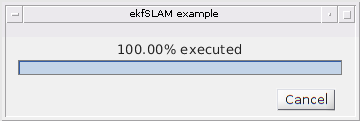

    if plotOnTheRun
        addpoints(deadRecHandle,deadReckoning(count,1),deadReckoning(count,2));
        addpoints(estTrajHandle,ekfSlamObj.State(1),ekfSlamObj.State(2));
        exampleHelperUpdateRobotAndLandmarks(ekfSlamObj.State,ekfSlamObj.StateCovariance, ...
            robotHandle,covarianceHandle,landmarkHandle);
        drawnow limitrate
    else
        % update the wait bar
        waitbar(count/numSamples,waitBarHandle, ...
            sprintf("%2.2f%% executed",count/numSamples*100));
        % Check for clicked Cancel button
        if getappdata(waitBarHandle,"canceling")
            break
        end
    end

end

Use the `delete` function to close the wait bar once all the computations are complete.

if ~plotOnTheRun
    delete(waitBarHandle);
end

## Visualize Map

Create a geographic plot with the ground truth from the GPS data. Plot the vehicle trajectory, along with all detected landmarks and their associated covariance, on the same geographic plot.

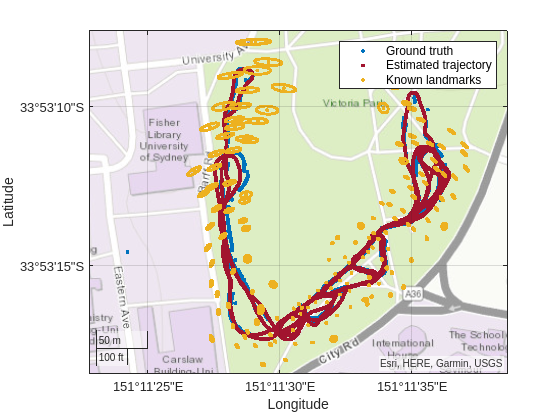

% get the corrected and predicted poses
[corrPoses,predPoses] = poseHistory(ekfSlamObj);


% show the map
exampleHelperShowMap(ekfSlamObj.State,ekfSlamObj.StateCovariance, ...
                     gpsLatLong,corrPoses,predPoses);

*Copyright 2021 The MathWorks, Inc.*